# Endpoint Evolution With RW Low Voltage

## Use knm2 Uniform Fit - Stack Scans

## Thierry Lasserre, November 5 2019

## General Settings

fixPar                = 'E0 Bkg Norm'; % free parameter
NonPoissonScaleFactor = 1.;
range                 = 90;
RunAnaArg = {'fixPar',fixPar,'DataType','Real',...
            'FSDFlag','BlindingKNM2','ELossFlag','KatrinT2',...
            'NonPoissonScaleFactor',NonPoissonScaleFactor,...
            'AnaFlag','StackPixel','chi2','chi2Stat'};

## Calculate E0 for : KNM2 Period 1 : rw = -50 mV

A1 = MultiRunAnalysis(RunAnaArg{:},'RunList','KNM2_beforeFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 2 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_beforeFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2397e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.100_Temax18709.096_Bin100_KatrinT2.mat


A1.exclDataStart = find(abs(range+A1.RunData.qU-18575)==min(abs(range+A1.RunData.qU-18575)));
A1.Fit;

RunAnalysis: Loading (E0 Norm Bkg) for Initialization from file ../../tritium-data/fit/Knm2/FitResult_InitModelObj_E0NormBkg_KNM2_beforeFix.mat 
----------BEGIN FIT MINUIT-------------- 
  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits
     3 'Par  #3   '  -0.13226      0.13226E-02     no limits
     4 'Par  #4   '   0.36855E-03  0.10000E-04     no limits
     5 'Par  #5   '    0.0000      0.10000E-04     no limits
     6 'Par  #6   '    0.0000      0.10000E-04     no limits
     7 'Par  #7   '    0.0000      0.10000E-04     no limits
     8 'Par  #8   '    0.0000      0.10000E-04     no limits
     9 'Par  #9   '    0.0000      0.10000E-04     no limits
    10 'Par #10   '    0.0000      0.10000E-04     no limits
    11 'Par #11   '    0.0000      0.10000E-0

E0P1 = A1.FitResult.par(2)+A1.ModelObj.Q_i;

## Calculate E0 for : KNM2 Period 2 : rw = -8mV

A2 = MultiRunAnalysis(RunAnaArg{:},'RunList','KNM2_afterFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_afterFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2489e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.087_Temax18709.095_Bin100_KatrinT2.mat


A2.exclDataStart = find(abs(range+A1.RunData.qU-18575)==min(abs(range+A1.RunData.qU-18575)));
A2.Fit;

RunAnalysis: Loading (E0 Norm Bkg) for Initialization from file ../../tritium-data/fit/Knm2/FitResult_InitModelObj_E0NormBkg_KNM2_afterFix.mat 
----------BEGIN FIT MINUIT-------------- 
  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits
     3 'Par  #3   '  -0.12685      0.12685E-02     no limits
     4 'Par  #4   '   0.24835E-02  0.24835E-04     no limits
     5 'Par  #5   '    0.0000      0.10000E-04     no limits
     6 'Par  #6   '    0.0000      0.10000E-04     no limits
     7 'Par  #7   '    0.0000      0.10000E-04     no limits
     8 'Par  #8   '    0.0000      0.10000E-04     no limits
     9 'Par  #9   '    0.0000      0.10000E-04     no limits
    10 'Par #10   '    0.0000      0.10000E-04     no limits
    11 'Par #11   '    0.0000      0.10000E-04

E0P2 = A2.FitResult.par(2)+A2.ModelObj.Q_i;

## Calculate E0 for : KNM2 Period 3 : rw = +193 mV

A3 = MultiRunAnalysis(RunAnaArg{:},'RunList','KNM2_after2ndFix');

-------------------Start MultiRunAnalysis Constructor----------------- 
---------------------Start RunAnalysis Constructor------------------- 
---------------------End RunAnalysis Constructor------------------- 
no new runs to convert 
ApplyStackingCuts: Exit Cut Routine after 1 Iterations 
Showing Stacked Data (data for Ring selected later) 
../../tritium-data/mat/Knm2/KNM2_after2ndFix
loading response function from file: ../../inputs/ResponseFunction/samakRF_Uniform_4.2531e+17cm2_IsX3.637e-22m2_NIS7_Bm4.23T_Bs2.52T_Ba6.311G_Temin18484.094_Temax18709.097_Bin100_KatrinT2.mat


A3.exclDataStart = find(abs(range+A1.RunData.qU-18575)==min(abs(range+A1.RunData.qU-18575)));
A3.Fit;

RunAnalysis: Loading (E0 Norm Bkg) for Initialization from file ../../tritium-data/fit/Knm2/FitResult_InitModelObj_E0NormBkg_KNM2_after2ndFix.mat 
----------BEGIN FIT MINUIT-------------- 
  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'Par  #1   '    0.0000      0.10000E-04     no limits
     2 'Par  #2   '    0.0000      0.10000E-04     no limits
     3 'Par  #3   '  -0.12101      0.12101E-02     no limits
     4 'Par  #4   '   0.52596E-02  0.52596E-04     no limits
     5 'Par  #5   '    0.0000      0.10000E-04     no limits
     6 'Par  #6   '    0.0000      0.10000E-04     no limits
     7 'Par  #7   '    0.0000      0.10000E-04     no limits
     8 'Par  #8   '    0.0000      0.10000E-04     no limits
     9 'Par  #9   '    0.0000      0.10000E-04     no limits
    10 'Par #10   '    0.0000      0.10000E-04     no limits
    11 'Par #11   '    0.0000      0.10000E

E0P3 = A3.FitResult.par(2)+A3.ModelObj.Q_i;

## Comparison of Mean Endpoint Values Before/After RW Fix's

%Data 
b    = [1 2 3];
x    = [E0P1 E0P2 E0P3];
ex   = [A1.FitResult.err(2) A3.FitResult.err(2) A3.FitResult.err(2)];
Data = [b' x' ex'];contrat
nbin = 3;

% Fit
parnames = 'mean'; 
ParIni   = mean([x]);
Args     = {ParIni, Data, '-c', 'min; imp'};
[ par, err, chi2min, errmat ] = fminuit('Chi2Gauss',Args{:});

  MINUIT RELEASE 96.03  INITIALIZED.   DIMENSIONS 150/150  EPSMAC=  0.89E-15

 PARAMETER DEFINITIONS:
    NO.   NAME         VALUE      STEP SIZE      LIMITS
     1 'mean      '    18574.       185.74         no limits
 **********
 **    1 **MIN
 **********

 FIRST CALL TO USER FUNCTION AT NEW START POINT, WITH IFLAG=4.
 START MIGRAD MINIMIZATION.  STRATEGY 1.  CONVERGENCE WHEN EDM .LT. 0.10E-03

 FCN=   130.8291     FROM MIGRAD    STATUS=INITIATE       4 CALLS        5 TOTAL
                     EDM= unknown      STRATEGY= 1      NO ERROR MATRIX       

  EXT PARAMETER               CURRENT GUESS       STEP         FIRST   
  NO.   NAME        VALUE          ERROR          SIZE      DERIVATIVE 
   1     mean       18574.        185.74        185.74       -563.28    

 MIGRAD MINIMIZATION HAS CONVERGED.

 MIGRAD WILL VERIFY CONVERGENCE AND ERROR MATRIX.
 COVARIANCE MATRIX CALCULATED SUCCESSFULLY

 FCN=   128.4038     FROM MIGRAD    STATUS=CONVERGED     14 CALLS       15 TOTAL
         

fprintf('=========================== Fit results ========================\n');

=========================== Fit results ========================


fprintf('  mean    = %.3f ± %.3f\n',par(1),err(1));

  mean    = 18573.639 ± 0.006


fprintf('  chi2min = %.2f for ndof = %d\n',chi2min,nbin-numel(ParIni));

  chi2min = 128.40 for ndof = 2


##  Display E0 Shift Versus Period 1, 2, 3

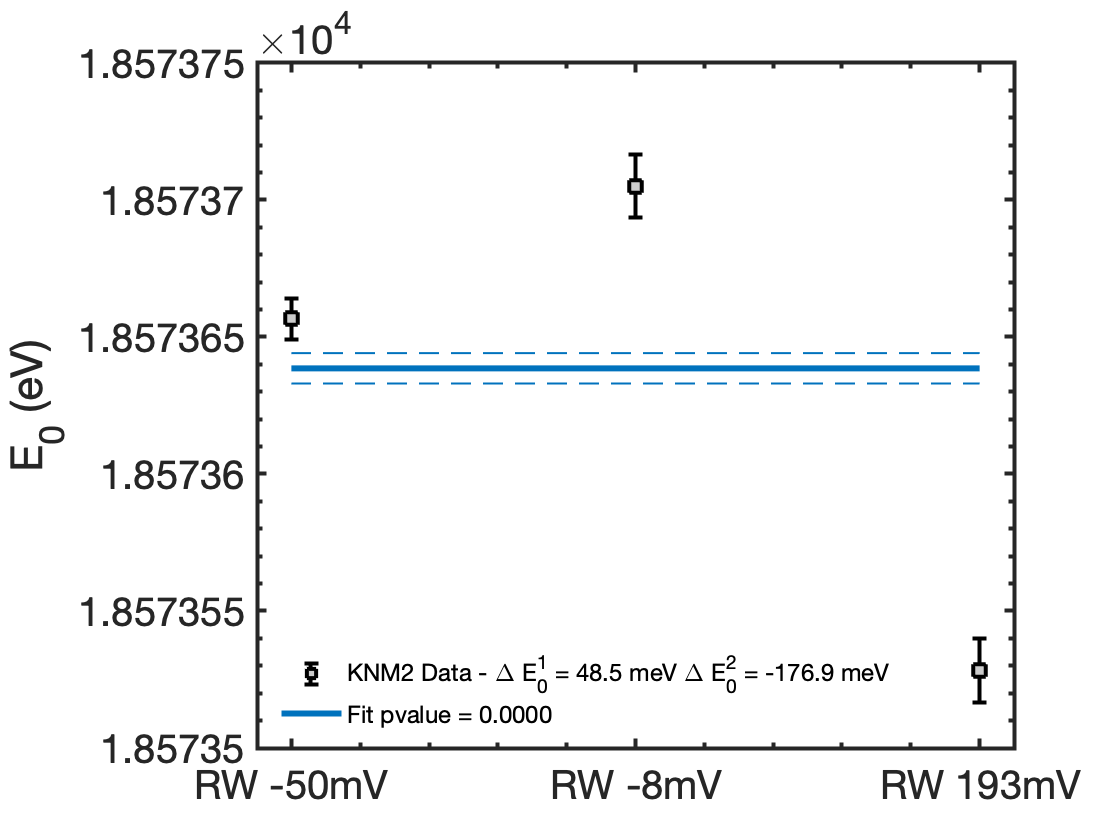

hdata = errorbar(Data(:,1),Data(:,2),Data(:,3),'ks',...
    'MarkerSize',8,'MarkerFaceColor',.8*[1 1 1],'LineWidth',2);
hold on;
hfit = line([1,3],[Model(par,Data(:,1)) Model(par,Data(:,1))],'LineWidth',3);
hfiteu = line([1,3],[Model(par+err,Data(:,1)) Model(par+err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hfited = line([1,3],[Model(par-err,Data(:,1)) Model(par-err,Data(:,1))],'LineWidth',1,'LineStyle','--');
hold off;
ylabel('E_0 (eV)','FontSize',24) 
legend([hdata hfit], ...
    sprintf('KNM2 Data - \\Delta E_0^1 = %.1f meV \\Delta E_0^2 = %.1f meV',...
    (E0P2-E0P1)*1e3,(E0P3-E0P2)*1e3), ...
    sprintf('Fit pvalue = %.4f',chi2pvalue(chi2min,1)),...
    'Location','SouthWest','FontSize',12)
grid off
xlim([0.9 3.1]);
xticks([1 2 3])
xticklabels({'RW -50mV','RW -8mV','RW 193mV'})
legend('boxoff');
PrettyFigureFormat('FontSize',24); 

##  Display E0 Shift Versus RW LV value

Here I correct the first period bby +42 mV, corresponding to the wrong grounding bias 

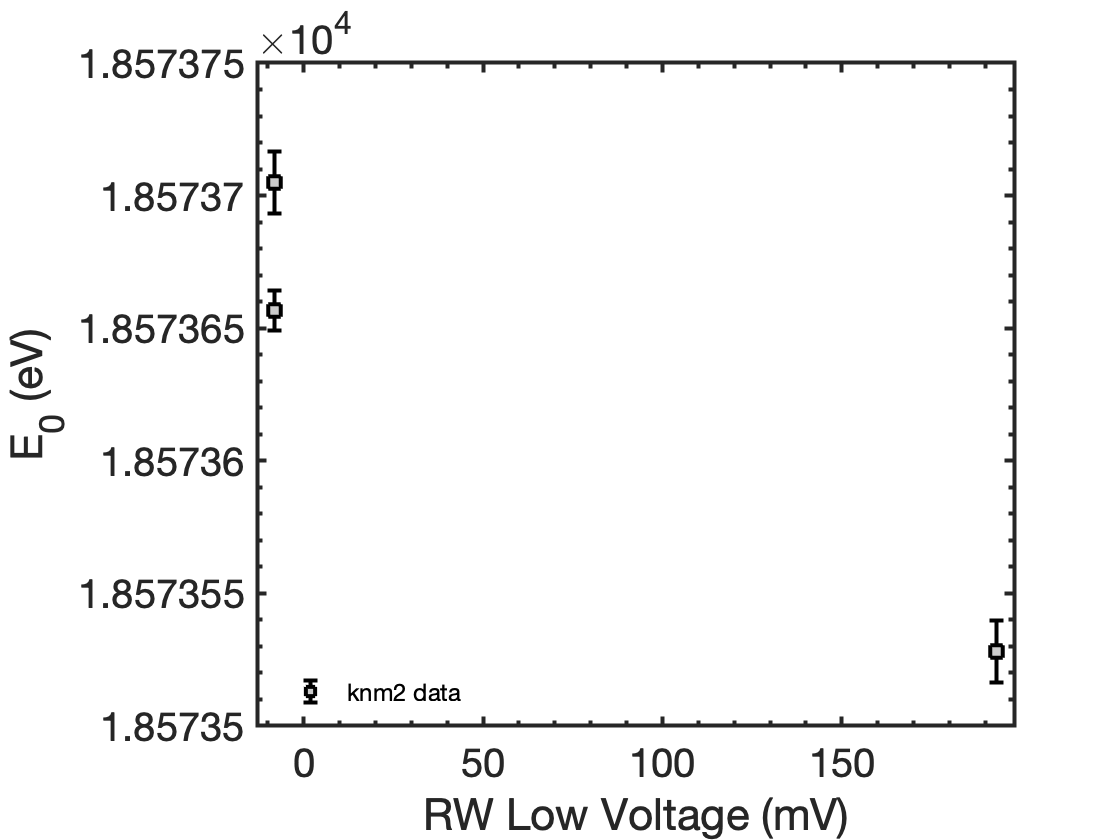

RWLV   = [-50+42 -8 193];
RWE0   = x;
RWE0E  = ex;
hdata = errorbar(RWLV,RWE0,RWE0E,'ks',...
    'MarkerSize',8,'MarkerFaceColor',.8*[1 1 1],'LineWidth',2);
legend('boxoff');
ylabel('E_0 (eV)','FontSize',24); 
xlabel({'RW Low Voltage (mV)'});
legend([hdata ],'knm2 data',...
    'Location','SouthWest','FontSize',12)
grid off
PrettyFigureFormat('FontSize',24); 
xlim([min(RWLV)-5 max(RWLV)+5]);